Question 1:

a. 

    To construct a bandpass filter in the image domain using only lowpass filters, you can create two lowpass filter kernels and convolve them together each way and subtracting the two and finally convoling the new kernel with the input image.

b.

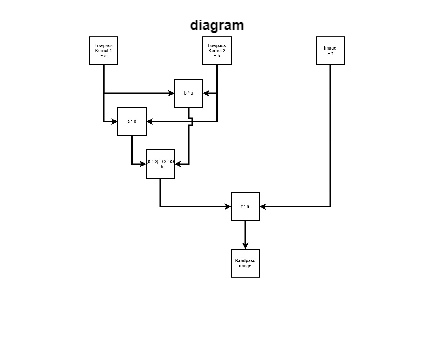

imshow(imread("diagram.jpg"));
title('diagram')

c.

    Input image f(x, y), lowpass kernel 1 h1(x, y), lowpass kernel 2 h2(x, y), Output image g(x, y).

    h12(x, y) = h1(x, y) * h2(x, y), h21(x, y) = h2(x, y) * h1(x, y)

    h(x, y) = h12(x, y) - h21(x, y)

    g(x, y) = f(x, y) * h(x, y)

d.

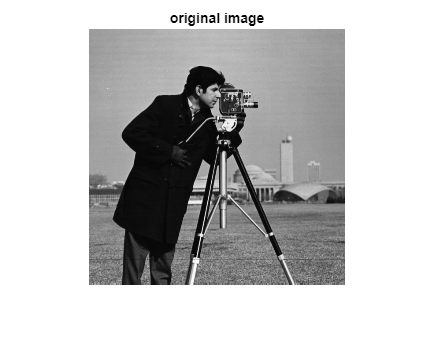

% original image
f_in = (imread("mycameraman2.png"));
imshow(f_in)
title('original image')

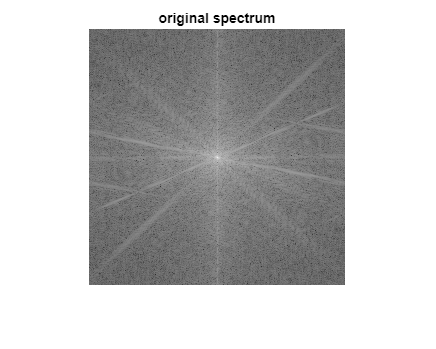

F_in = fftshift(fft2(f_in));
magnitude = abs(F_in);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('original spectrum')


% normal lowpass a
lowpass1 = fspecial('average', 3)

lowpass1 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


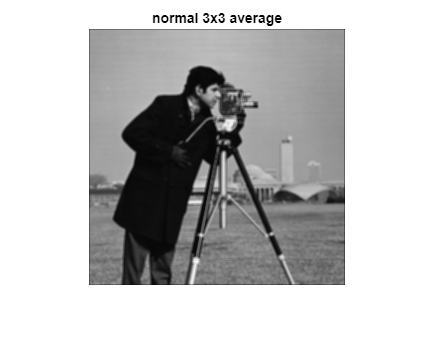

a = imfilter(f_in, lowpass1, 'conv');
imshow(a);
title('normal 3x3 average')

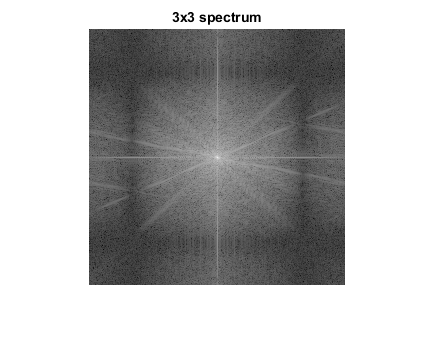

A = fftshift(fft2(a));
magnitude = abs(A);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('3x3 spectrum')


% normal lowpass b
lowpass2 = fspecial('average', 9)

lowpass2 =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


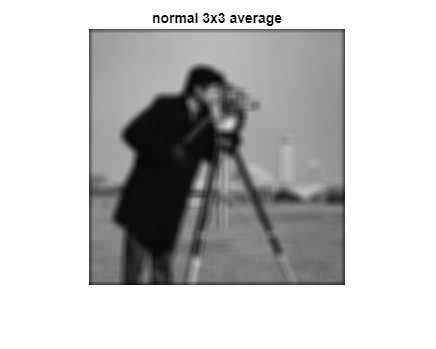

b = imfilter(f_in, lowpass2, 'conv');
imshow(b);
title('normal 3x3 average')

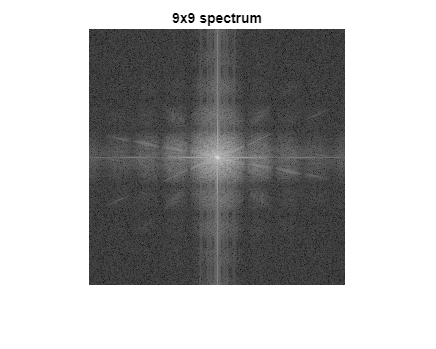

B = fftshift(fft2(b));
magnitude = abs(B);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('9x9 spectrum')


% a * b
ab = imfilter(lowpass1, lowpass2, 'conv')

ab =     0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123


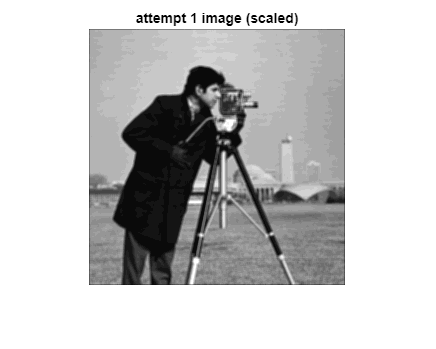

f_ab = imfilter(f_in, ab, 'conv');
imshow(f_ab * 10);
title('attempt 1 image (scaled)')

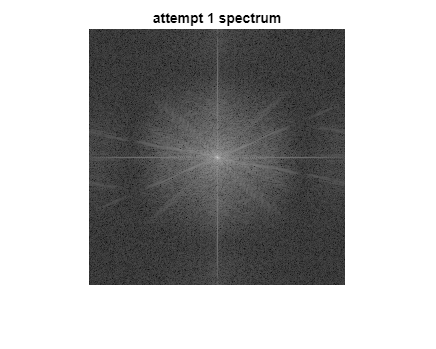

A = fftshift(fft2(f_ab));
magnitude = abs(A);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('attempt 1 spectrum')


% b * a
ba = imfilter(lowpass2, lowpass1, 'conv')

ba =     0.0055    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0055
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0082    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0082
    0.0055    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0055


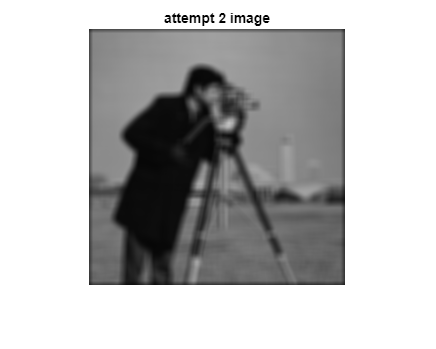

f_ba = imfilter(f_in, ba, 'conv');
imshow(f_ba);
title('attempt 2 image')

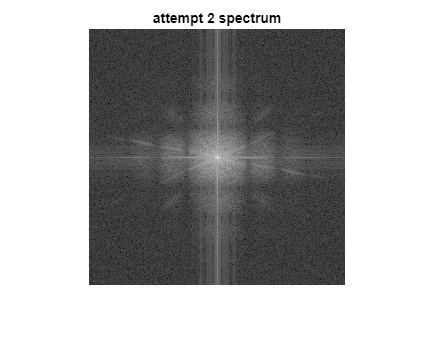

B = fftshift(fft2(f_ba));
magnitude = abs(B);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('attempt 2 spectrum')

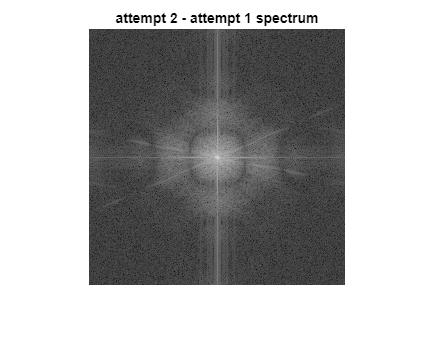


% filtered subtraction
bp = abs(f_ba - f_ab);
BP = fftshift(fft2(bp));
magnitude = abs(BP);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('attempt 2 - attempt 1 spectrum')

e.

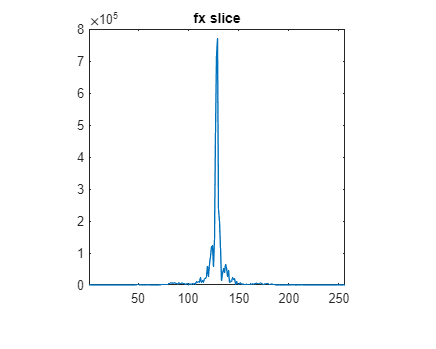

plot(magnitude(128, :));
title('fx slice')
xlim([1 256])

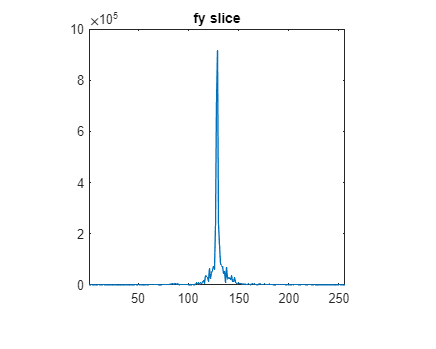

plot(magnitude(:, 128));
title('fy slice')
xlim([1 256])

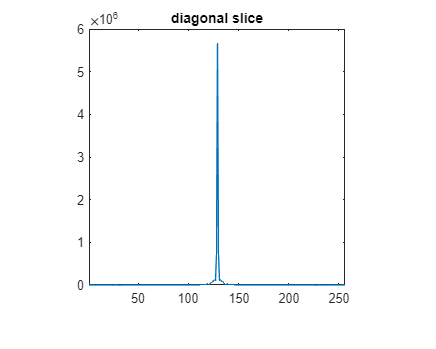

diagonal_slice = zeros(1, min(size(magnitude)));
for i = 1:min(size(magnitude))
    diagonal_slice(i) = magnitude(i, i);
end
plot(real(diagonal_slice));
title('diagonal slice')
xlim([1 256])

    Most of the image has low spatial frequency so a large spike will be seen in the center.

f.

    I was not able to successfully construct a bandpass filter to eliminate the low frequency data.